addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{23}$$


Need paths in y and xtheta directions.

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 2; % S23
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = 0*[+1, 0] + 0*[0, +1];                                   % pof = (+0,+0) degrees % y path
% ptf = -0.707106781186548*[+1, 0] + -0.707106781186548*[0, +1]; 
% ptf = -deg2rad(18)*[+1, 0] + deg2rad(18)*[0, +1];
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
dirn = 1;
% dirn = 1;
% dirn = -1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path23 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path23, symstr, dnum );
path = path23;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);
exportsetupdlg;
S23_data_y = S_data; save('Data\case_1_S23_y.mat', 'S23_data_y'); % , '-append'
% S23_data_xy = S_data; save('Data\case_1_S23_xy.mat', 'S23_data_xy'); % , '-append'
% S23_data_mytheta = S_data; save('Data\case_1_S23_mytheta.mat', 'S23_data_mytheta'); % , '-append'

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{41}$$


% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 4; % S23
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);
[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = 0*[+1, 0] + 0*[0, +1];                                  % pof = (+0,+0) degrees % y path
% ptf = +0.707106781186548*[+1, 0] + +0.707106781186548*[0, +1]; 
% ptf = -deg2rad(18)*[+1, 0] + deg2rad(18)*[0, +1];
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
dirn = -1;
% dirn = +1;
% dirn = -1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path23 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path23, symstr, dnum );
path = path23;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);
exportsetupdlg;
S41_data_y = S_data; save('Data\case_1_S41_y.mat', 'S41_data_y'); % , '-append'
% S41_data_xmy = S_data; save('Data\case_1_S41_xmy.mat', 'S41_data_xmy'); % , '-append'
% S41_data_ytheta = S_data; save('Data\case_1_S41_ytheta.mat', 'S41_data_ytheta'); % , '-append'

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');
load('Data\case_1_S23_y.mat'); load('Data\case_1_S23_xy.mat'); load('Data\case_1_S23_mytheta.mat');
load('Data\case_1_S41_y.mat'); load('Data\case_1_S41_xmy.mat'); load('Data\case_1_S41_ytheta.mat');

#### 
$$S_{23} \leftrightarrow S_{41}$$


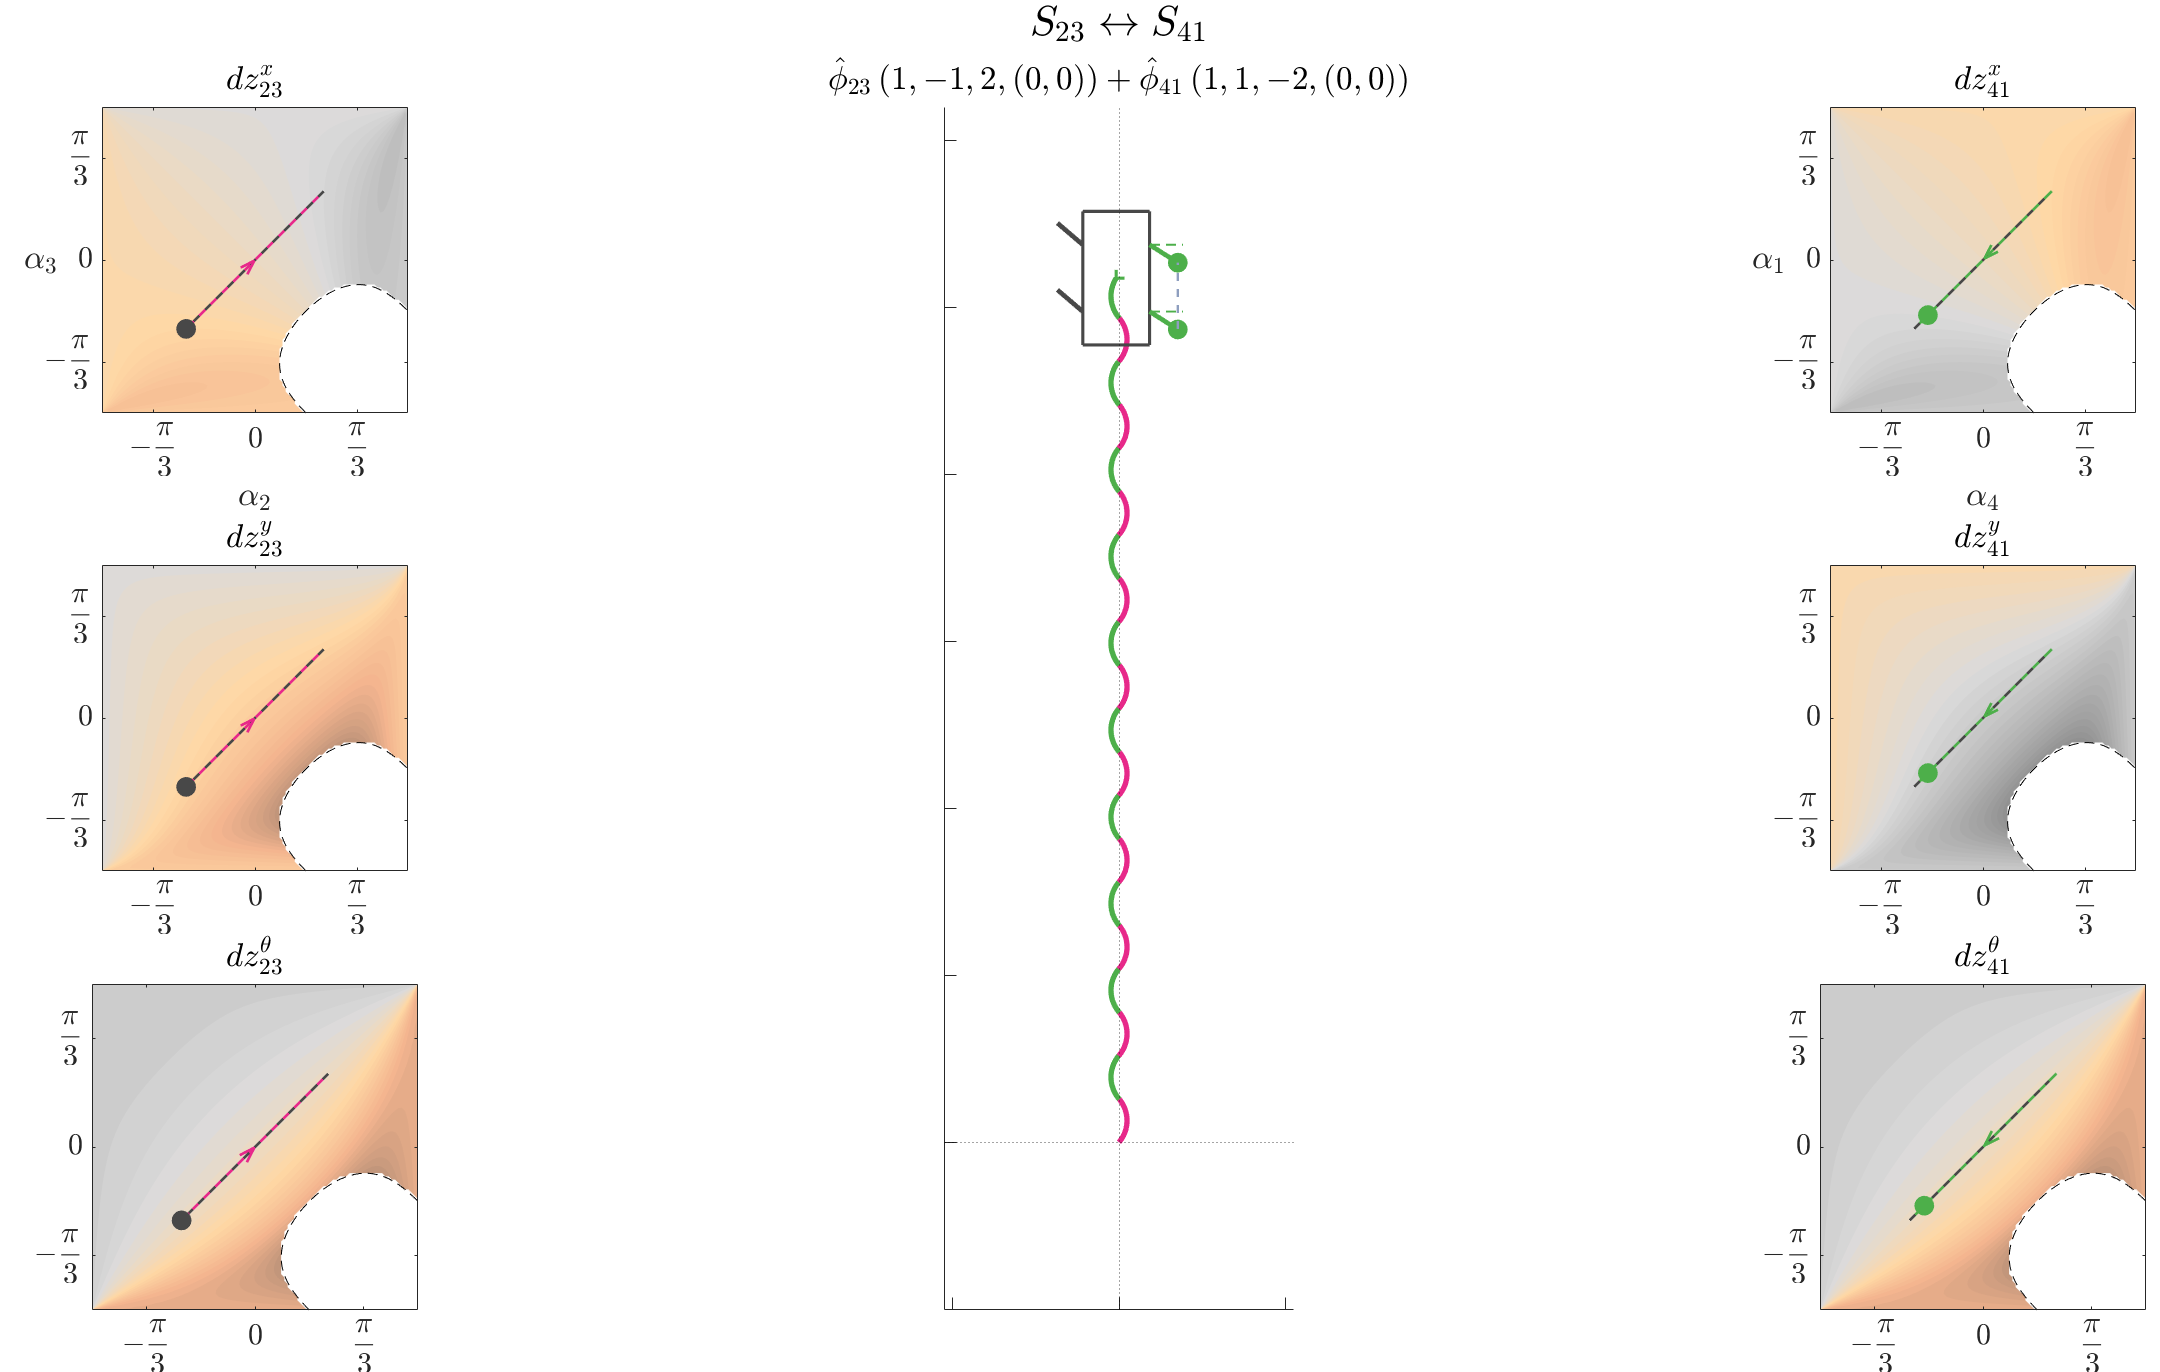

dataij = [];
dataij.vidF = true; % true % false
dataij.u = [+100, +100]/100; % y path
% dataij.u = [+100, +100]/100; % x path
% dataij.u = [+100, -100]/100; % y path 2.0
% dataij.gaitC_num = 1; % just for theta path
% dataij.u = [+100, +100]/100; % theta path
% dataij.u = [-100, +100]/100; % y path 3.0
S23_data_y{1}.fA = 0.7;
S41_data_y{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S23_data_y, S41_data_y, dataij);

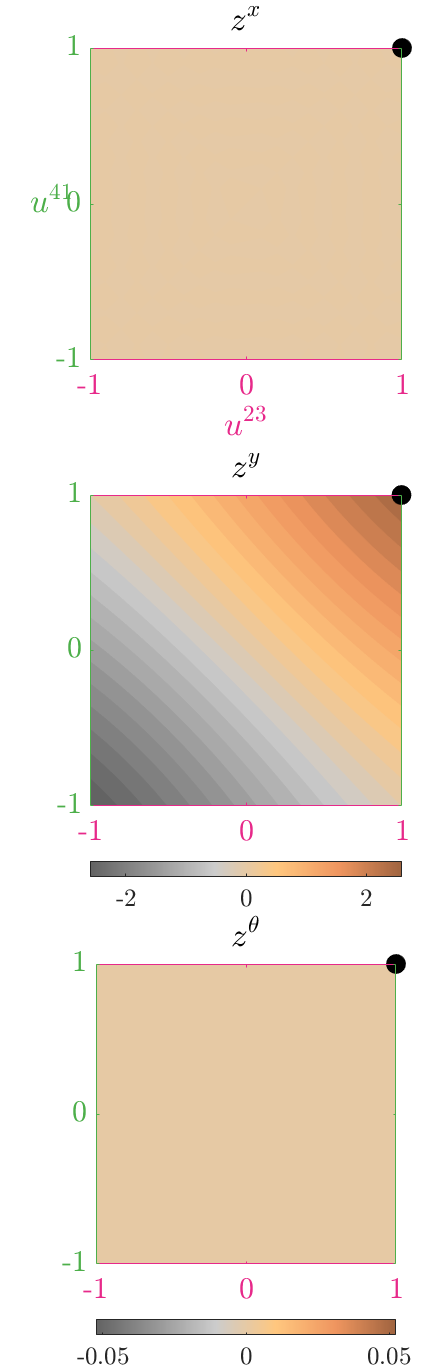

plotnetdispofnoslip2bgaits(S23_data_y, S41_data_y, dataij);

save('Data\case_1_S23toS41_y_gait.mat','dataij');
% S23_data_xy{1}.fA = 0.7;
% S41_data_xmy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_xy, S41_data_xmy, dataij);
% plotnetdispofnoslip2bgaits(S23_data_xy, S41_data_xmy, dataij);
% save('Data\case_1_S23toS41_x_gait.mat','dataij');
% S23_data_xy{1}.fA = 0.7;
% S41_data_xmy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_xy, S41_data_xmy, dataij);
% plotnetdispofnoslip2bgaits(S23_data_xy, S41_data_xmy, dataij);
% save('Data\case_1_S23toS41_y_gait_2.mat','dataij');
% S23_data_mytheta{1}.fA = 0.7;
% S41_data_ytheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_mytheta, S41_data_ytheta, dataij);
% plotnetdispofnoslip2bgaits(S23_data_mytheta, S41_data_ytheta, dataij);
% save('Data\case_1_S23toS41_theta_gait.mat','dataij');
% S23_data_mytheta{1}.fA = 0.7;
% S41_data_ytheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S23_data_mytheta, S41_data_ytheta, dataij);
% plotnetdispofnoslip2bgaits(S23_data_mytheta, S41_data_ytheta, dataij);
% save('Data\case_1_S23toS41_y_gait_3.mat','dataij');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{13}$$


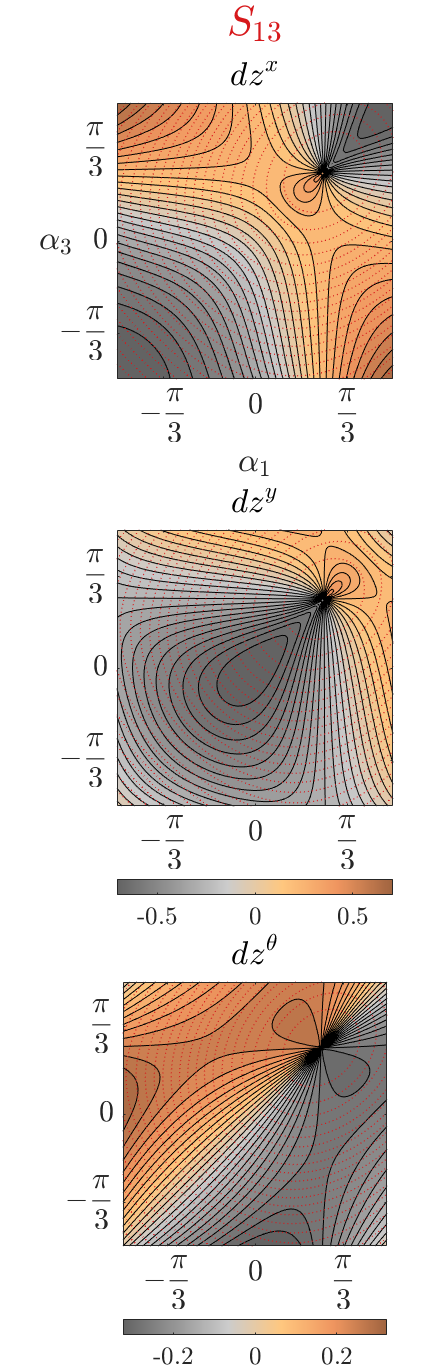

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 5; % S13
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);

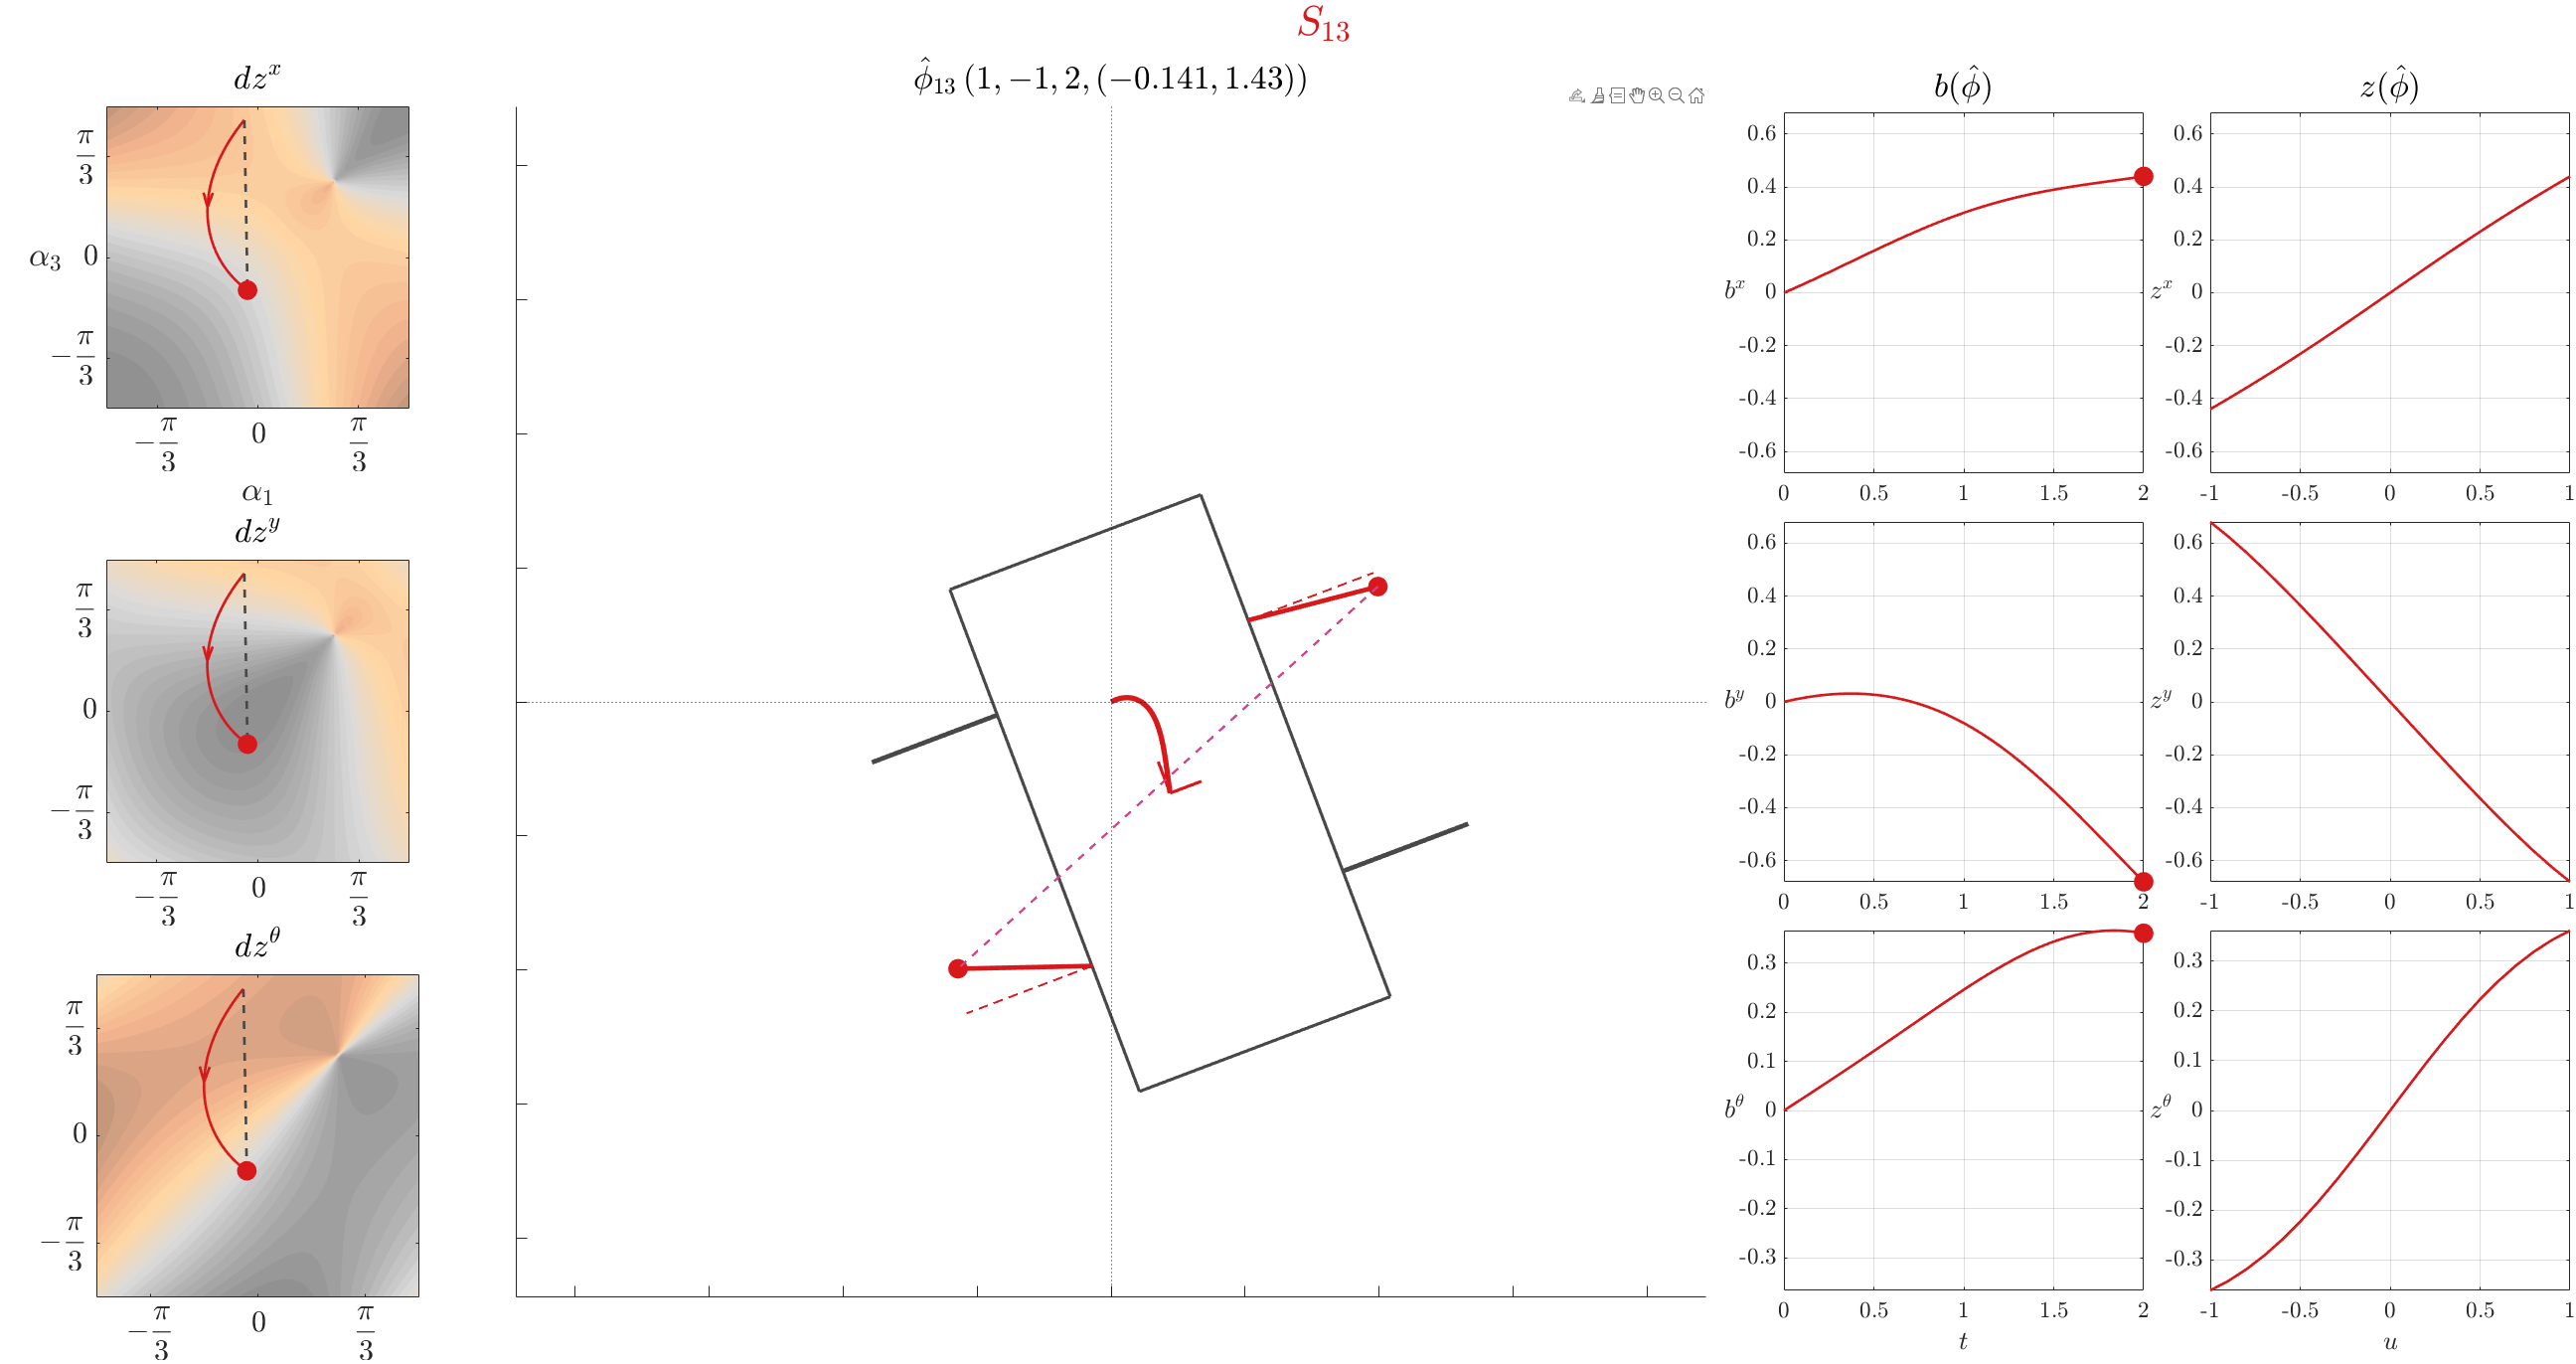

[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
% ptf = 0*[+1, 0] + 0*[0, +1]; % y path
ptf = -(pi/6)*[+1, 0] + (pi/6)*[0, +1]; % theta path
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
% dirn = -1;
dirn = +1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path13 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path13, symstr, dnum );
path = path13;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% exportsetupdlg;
% S13_data_mxy = S_data; save('Data\case_1_S13_mxy.mat', 'S13_data_mxy');
S13_data_xmytheta = S_data; save('Data\case_1_S13_xmytheta.mat', 'S13_data_xmytheta');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

#### 
$$S_{24}$$


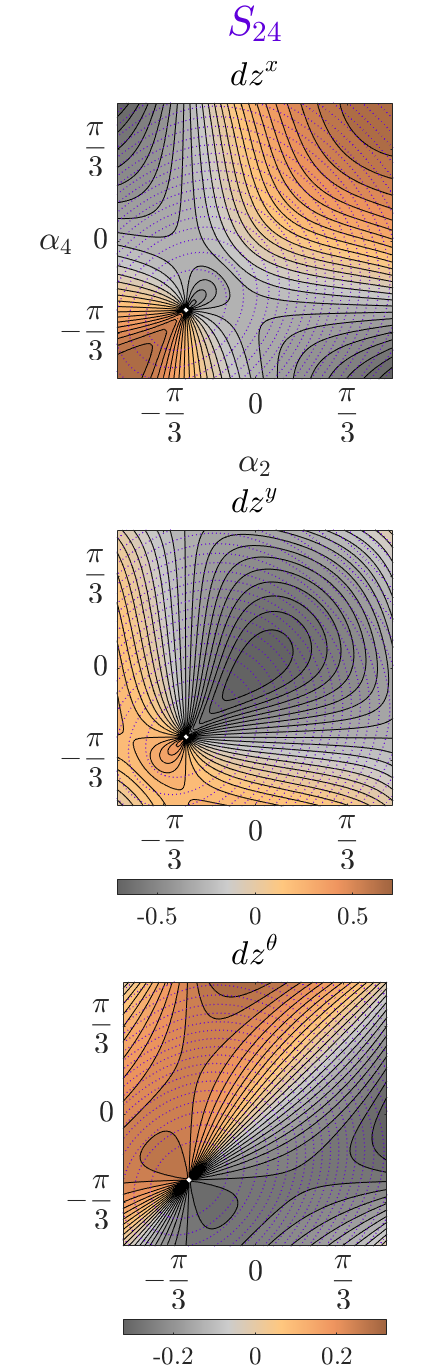

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 6; % S24
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
qlevel2noslip_mp(S_data);

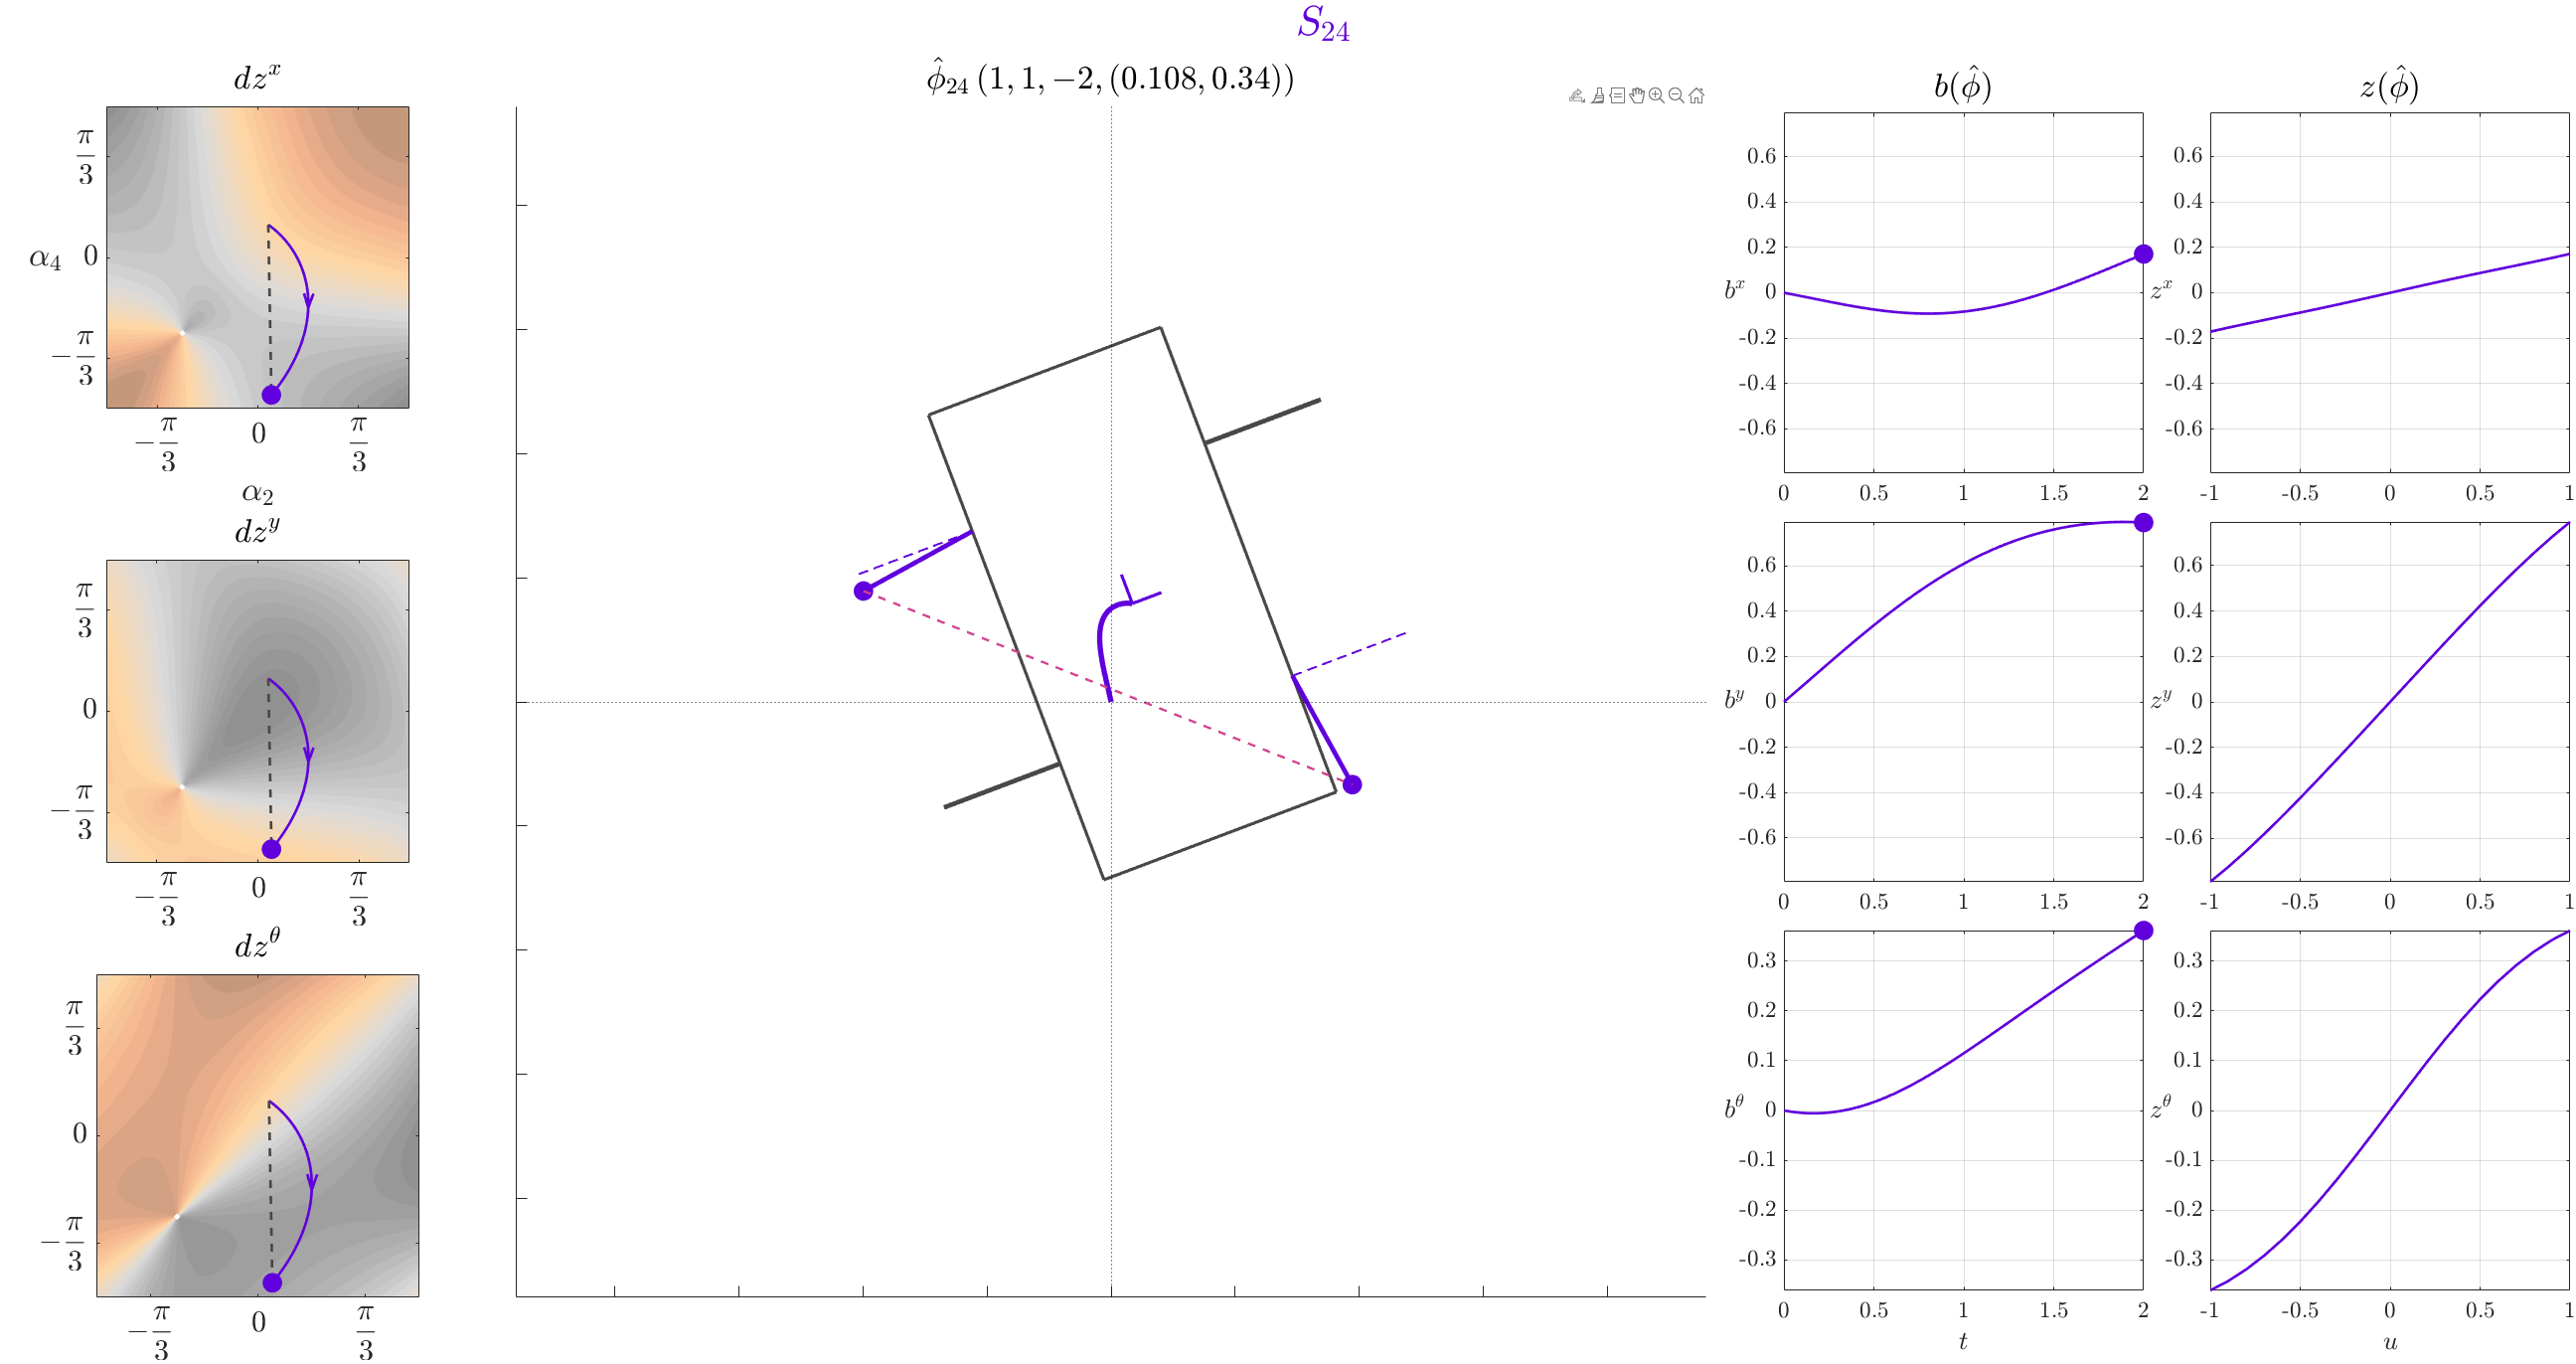

[dz, dpsi, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
% ptf = 0*[+1, 0] + 0*[0, +1]; % y path
ptf = (pi/6)*[+1, 0] + -(pi/6)*[0, +1]; % theta path
%%%%%%%%%%%%%%%%%%%%%%%%%
t = [1, 1];
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
% dirn = -1;
dirn = -1;
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path24 = Path2( ank, a, l, dz, dpsi, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
Path2.compute_trajectory( path24, symstr, dnum );
path = path24;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{1}.skp_path = [1 20];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% exportsetupdlg;
% S24_data_xy = S_data; save('Data\case_1_S24_xy.mat', 'S24_data_xy');
S24_data_xytheta = S_data; save('Data\case_1_S24_xytheta.mat', 'S24_data_xytheta');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');
load('Data\case_1_S13_mxy.mat'); 
load('Data\case_1_S13_xmytheta.mat');
load('Data\case_1_S24_xy.mat'); 
load('Data\case_1_S24_xytheta.mat');

#### 
$$S_{13} \leftrightarrow S_{24}$$


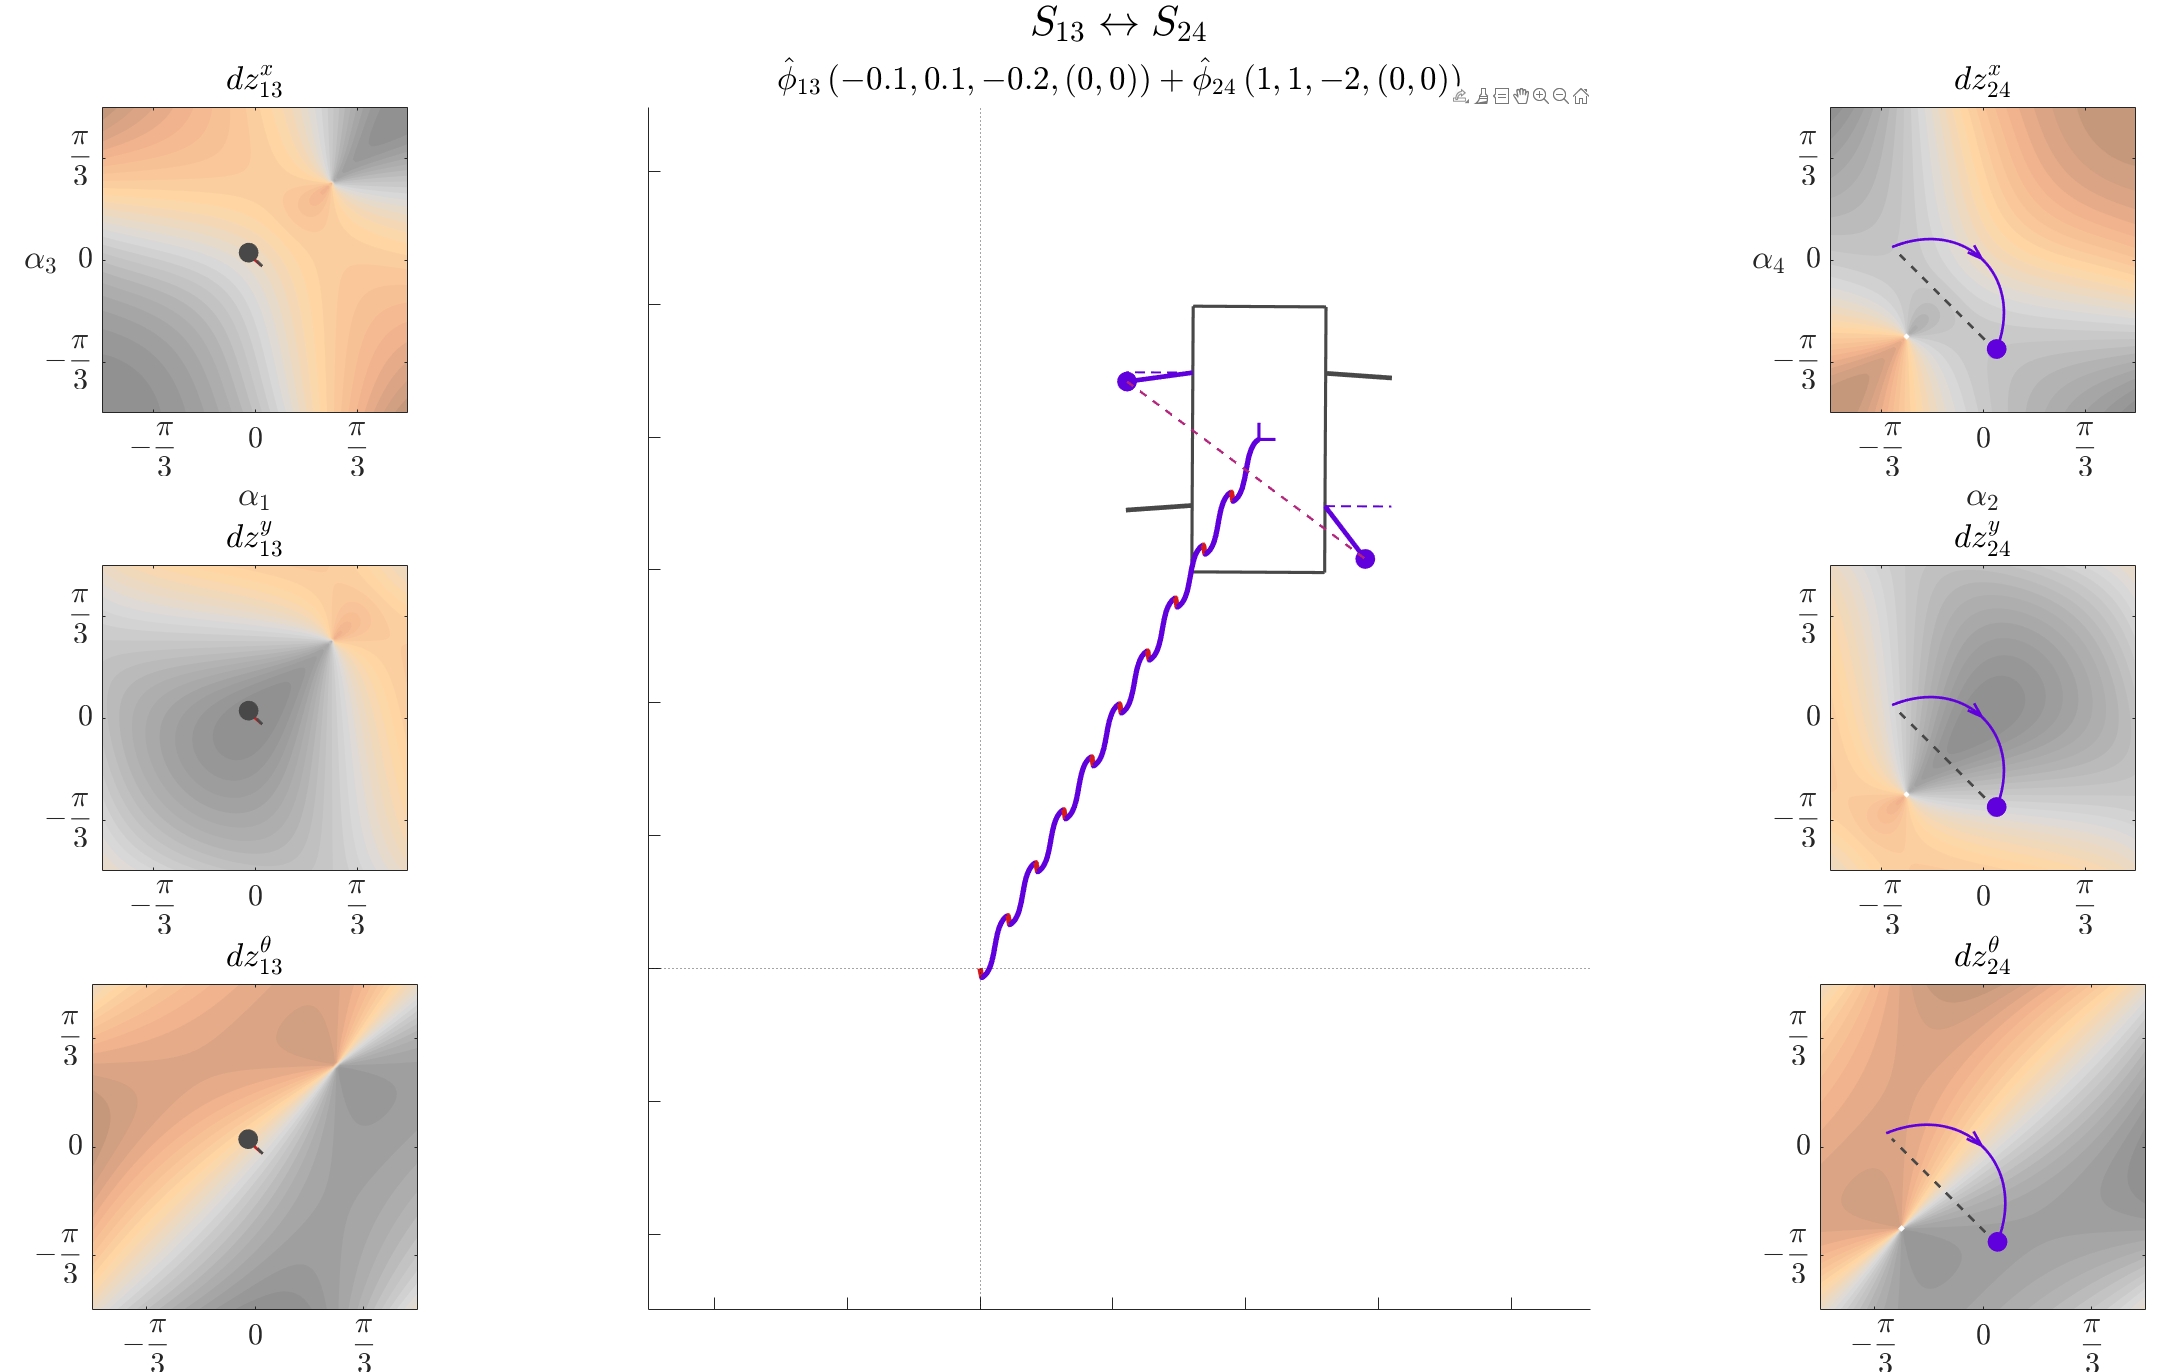

dataij = [];
dataij.vidF = false; % true % false
% dataij.u = [+100, +100]/100; % y path
% dataij.gaitC_num = 1; % just for theta path
% dataij.u = [+100, +100]/100; % theta path
% dataij.u = [-100, +100]/100; % x path
dataij.u = [-10, +100]/100;
% S13_data_mxy{1}.fA = 0.7;
% S24_data_xy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_data_mxy, S24_data_xy, dataij);
% plotnetdispofnoslip2bgaits(S13_data_mxy, S24_data_xy, dataij);
% save('Data\case_1_S13toS24_y_path.mat','dataij');
% S13_data_xmytheta{1}.fA = 0.7;
% S24_data_xytheta{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_data_xmytheta, S24_data_xytheta, dataij);
% plotnetdispofnoslip2bgaits(S13_data_xmytheta, S24_data_xytheta, dataij);
% save('Data\case_1_S13toS24_theta_path.mat','dataij');
% S13_data_mxy{1}.fA = 0.7;
% S24_data_xy{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_data_mxy, S24_data_xy, dataij);
% plotnetdispofnoslip2bgaits(S13_data_mxy, S24_data_xy, dataij);
% save('Data\case_1_S13toS24_x_path.mat','dataij');
S13_data_mxy{1}.fA = 0.7;
S24_data_xy{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S13_data_mxy, S24_data_xy, dataij);

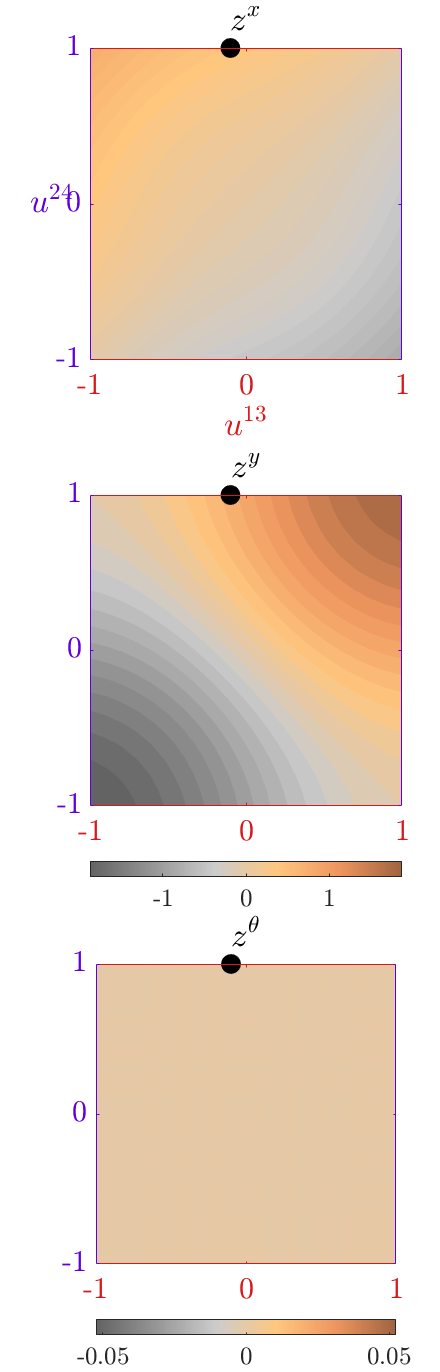

plotnetdispofnoslip2bgaits(S13_data_mxy, S24_data_xy, dataij);

save('Data\case_1_S13toS24_test_path.mat','dataij');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

## Conservativity of the Kinematics

In this section, we shall explore the conservative nature of the local connection with two sequential paths. The first path satisfies the no-slip gait constraint and the second path starts at the end of the first path and returns to the initial.

% % % load('Data\case_1_S12_y.mat'); si = 1;
% % % 
% % % % Get the +50% path; we won't use the full path since the connecting path passes through the robot singularity.
% % % ic = S12_data_y{5}.initial_condition{15};
% % % fc = S12_data_y{5}.final_condition{15};
% % % path_1 = S12_data_y{5}.open_trajectory{15};
% % % zx = S12_data_y{5}.net_displacement(1,15);
% % % zy = S12_data_y{5}.net_displacement(2,15);
% % % ztheta = S12_data_y{5}.net_displacement(3,15);
% % % 
% % % % compute the second path from the end of the first path back to the initial condition of the first path
% % % delt = path_1{1}(end);
% % % deli = ic(1) - fc(1); slopei = deli/delt;
% % % delj = ic(2) - fc(2); slopej = delj/delt;
% % % syms a l t x y theta alpha_1 alpha_2 real
% % % ai_0 = fc(1); aj_0 = fc(2);
% % % dz_path_2 = matlabFunction(simplify([-TeLg_old(ztheta)*A_1_12(:,1:2); eye(2,2)]*[slopei; slopej], 'Steps', 10), 'Vars', [a l t x y theta alpha_1 alpha_2]);
% % % [tf, qf] = ode45( @(t,y) dz_path_2(1, 1, t, y(1), y(2), y(3), y(4), y(5)), path_1{1}, [zx; zy; ztheta; fc(1); fc(2)] );
% % % path_2 = cell(size(path_1));
% % % path_2{1} = tf(:)';
% % % path_2{2} = qf(:,1)';
% % % path_2{3} = qf(:,2)';
% % % path_2{4} = qf(:,3)';
% % % path_2{5} = qf(:,4)';
% % % path_2{6} = qf(:,5)';

Let's plot the translation trajectory to see how the system behaves,

% % % figure()
% % % plot(path_1{2}, path_1{3}, 'r', 'LineWidth', 1.2);
% % % hold on; grid on; axis equal square;
% % % plot(path_2{2}, path_2{3}, 'r--', 'LineWidth', 1.2);
% % % axis([-1 1 -1 1]);

Not exactly conservative-- this will be point of exploration for future work.

## Kinematic of a 3-link system with distal ends hinged

addpath 'Utility Functions'\;
sympref('AbbreviateOutput',false);
syms x y theta u v beta real
M2v_SE2 = @(M) simplify([M(1,3); 
                M(2,3);
                atan(M(2,1)/M(1,1))], 'Steps', 10, ...
                'IgnoreAnalyticConstraints', true);
L_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(h)*v2M_SE2(g)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); %%
R_h_ofg = @(g,h) simplify(M2v_SE2(v2M_SE2(g)*v2M_SE2(h)), ...
    'Steps', 10, 'IgnoreAnalyticConstraints', true); %%
T_gL_h = @(g,h) jacobian(L_h_ofg(g,h), g); T_gR_h = @(g,h) jacobian(R_h_ofg(g,h), g); %%
g_vec = [x;
         y;
         theta]; %%
h_vec = [u;
         v;
         beta]; %%
g_mat = v2M_SE2(g_vec); %%
T_g_to_T_hg = T_gL_h(g_vec, h_vec); %%
T_g_to_T_gh = T_gR_h(g_vec, h_vec); %%
gInv_mat = simplify(inv(g_mat), 'Steps', 10);
gInv_vec = M2v_SE2(gInv_mat); %%
TgLgInv = simplify(subs(T_g_to_T_hg, [x, y, theta, u, v, beta],...
    [x, y, theta, gInv_vec(1), gInv_vec(2), gInv_vec(3)])); %%
TeRg = simplify(subs(T_g_to_T_gh, [x, y, theta, u, v, beta], ...
                [0, 0, 0, x, y, theta])); %%
AdjInvMap = @(k) simplify(...
    subs(TgLgInv, theta, k(3))*subs(TeRg, [x y], [k(1) k(2)])...
    , 'Steps', 10); %%
theta_sel = [0,0,1]'; x_sel = [1,0,0]'; y_sel = [0,1,0]';

A 3-link system with both its distal ends are hinged to the locomotion plane. Let the distance to each leg base and length of each leg be 1 unit.

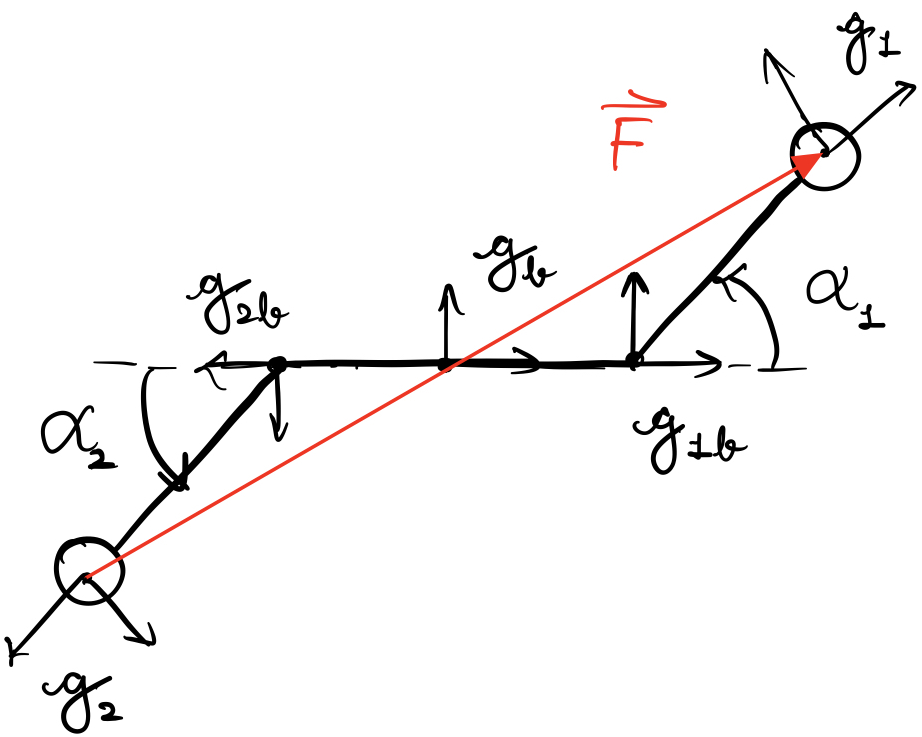

syms a l alpha_1 alpha_2 theta real

syms alpha_i
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];
h_ib__i_func = matlabFunction(h_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__i = AdjInvMap(h_ib__i);
J_ib__i_func = matlabFunction(J_ib__i, 'Vars', [a, l, alpha_i]);
J_ib__j_func = matlabFunction(zeros(3,3), 'Vars', [a, l, alpha_i]);
h_b__1b = [1, 0, 0]'; h_b__2b = [-1, 0, 0]';
h_1b__1 = h_ib__i_func(1, 1, alpha_1); h_2b__2 = h_ib__i_func(1, 1, alpha_2);
J_1b__1 = AdjInvMap(h_1b__1); J_2b__2 = AdjInvMap(h_2b__2);
J_1b__2 = J_ib__j_func(1, 1, alpha_1); J_2b__1 = J_ib__j_func(1, 1, alpha_2);
h_b__1 = seqSE2transformation([h_b__1b, h_1b__1])
h_b__2 = seqSE2transformation([h_b__2b, h_2b__2])
J_b__1 = AdjInvMap(h_b__1)
J_b__2 = AdjInvMap(h_b__2)
J_1_full = [J_b__1,...
    J_1b__1*theta_sel, J_2b__1*theta_sel]
J_2_full = [J_b__2,...
    J_1b__2*theta_sel, J_2b__2*theta_sel]
C = [eye(2,2),zeros(2,1)];
pfaff = [C*J_1_full;
            C*J_2_full]
A = simplify((transpose(pfaff(:,1:3))*pfaff(:,1:3))\transpose(pfaff(:,1:3))*pfaff(:,4:end)) % local connection
A_1__x_f = matlabFunction(A(1, 1), 'Vars', [alpha_1, alpha_2]); A_2__x_f = matlabFunction(A(1, 2), 'Vars', [alpha_1, alpha_2]);
A_1__y_f = matlabFunction(A(2, 1), 'Vars', [alpha_1, alpha_2]); A_2__y_f = matlabFunction(A(2, 2), 'Vars', [alpha_1, alpha_2]);
A_1__theta_f = matlabFunction(A(3, 1), 'Vars', [alpha_1, alpha_2]); A_2__theta_f = matlabFunction(A(3, 2), 'Vars', [alpha_1, alpha_2]);
F_vec = h_b__2 - h_b__1
F = simplify((C*(h_b__2 - h_b__1))'*C*(h_b__2 - h_b__1),'Steps',10)
F_f = matlabFunction(F, 'Vars', [alpha_1, alpha_2]);
rot_in_ij = [cos(theta), -sin(theta);
            sin(theta), cos(theta)];
rot_in_ij = matlabFunction(rot_in_ij, 'Vars', theta);
gradF = simplify([diff(F, alpha_1), diff(F, alpha_2)]', 'Steps', 10) % slipping shape velocities
RgradF = simplify(round(rot_in_ij(-pi/2))*gradF, 'Steps', 10) % sticking shape velocities
gradF_f  =  matlabFunction(gradF, 'Vars', [alpha_1, alpha_2]);
RgradF_f =  matlabFunction(RgradF, 'Vars', [alpha_1, alpha_2]);
dz = simplify(-A*RgradF, 'Steps', 10) % stratified curvature
dz_f = matlabFunction(dz, 'Vars', [alpha_1, alpha_2]);
% Save the data
save('Data\3linkdistalhinges', "dz_f", "RgradF_f", "gradF_f", "F_f",...
    "A_2__theta_f", "A_1__theta_f", "A_2__y_f", "A_1__y_f", "A_2__x_f", "A_1__x_f", ...
    "J_1_full", "J_2_full", "h_b__1", "h_b__2");

## Velocity Basis for a planar, symmetric quadrupedal robot

Here, we take the path constraints and convert it into the velocity basis for the quadrupedal robot.